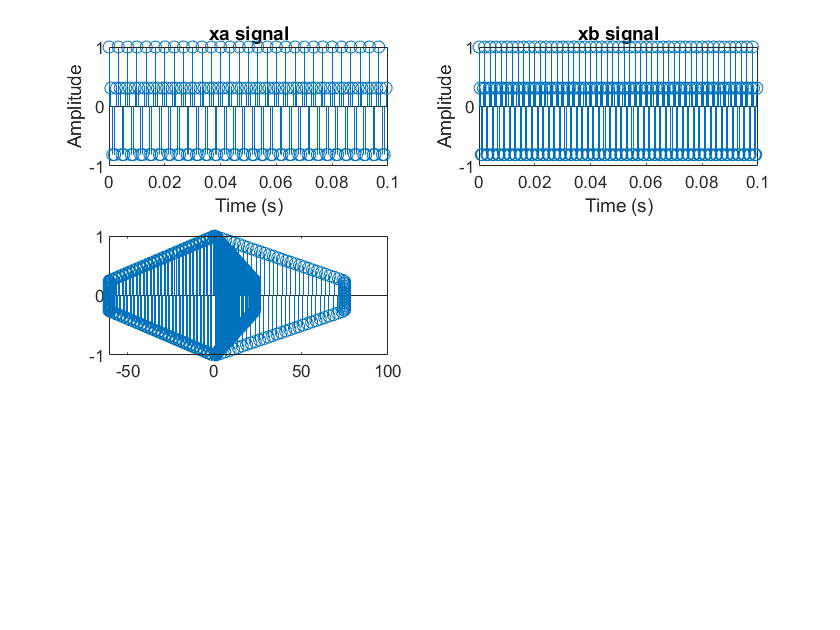

%% Signal x2a of 300Hz
f2a = 300 ; %Freqeuncy of signal in Hz
fs2a = 5*f2a ; %Sampling frequency for discrete-time signal 
L2a = 0.1*fs2a; %Signal length (no. of samples)- 0.1s 
t2a = [0:L2a-1]/fs2a; %Signal sampling instants 
x2a = cos(2*pi*f2a*t2a); %Sinusoidal signal 


% Signal x2b of 500Hz
f2b = 500 ; %Freqeuncy of signal in Hz
fs2b = 5*f2b; %Sampling frequency for discrete-time signal 
L2b = 0.1*fs2b; %Signal length (no. of samples) - 0.1s 
t2b = [0:L2b-1]/fs2b; %Signal sampling instants 
x2b = cos(2*pi*f2b*t2b); %Sinusoidal signal 


%Plotting 
figure(1);

% Plotting xa
subplot(3,2,1);
stem(t2a,x2a);
xlabel('Time (s)');
ylabel('Amplitude');
title('xa signal');

% Plotting xb
subplot(3,2,2);
stem(t2b,x2b);
xlabel('Time (s)');
ylabel('Amplitude');
title('xb signal');
subplot(3,2,3)
y=convn(x2a,x2b);
tc = linspace(-1,1,length(y));

stem(y,tc)


m=x2a+x2b;

Matrix dimensions must agree.

plot(m)

